# Test CNN Model

### Read CNN Model

clc;
clear;
net = load('2_trained_CNN.mat');
net = net.trainedNetwork_1;

### Plot Performance of CNN Model

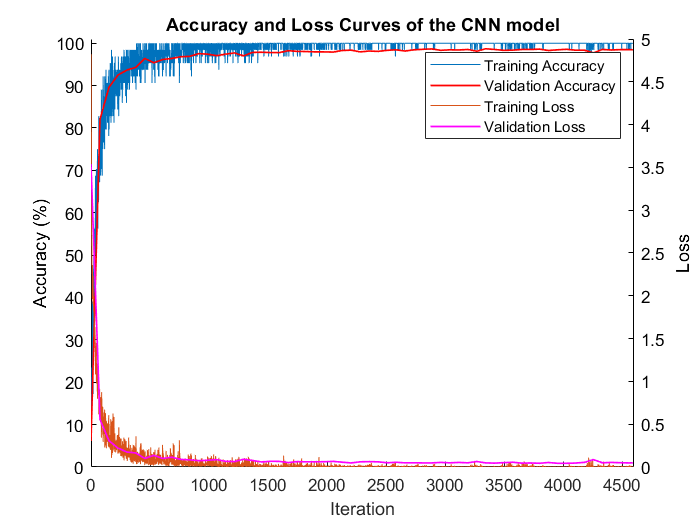

% Load training performance
performance = load('3_CNN_performance.mat');
performance = performance.trainInfoStruct_1;
% Remove NaN from data since validation is only 
% performed for every 76 iterations
validation_accuracy = performance.ValidationAccuracy;
validation_accuracy = validation_accuracy(~isnan(validation_accuracy))';
validation_loss = performance.ValidationLoss;
validation_loss = validation_loss(~isnan(validation_loss))';

% Plot training accuracy and training loss
fig = figure;
axes = gca;
hold on;

% Plot training and validation accuracy
yyaxis left;
plot(performance.TrainingAccuracy);
x = [0:76:4560];
x(end + 1) = 4590;
plot(x, validation_accuracy, '-r', 'LineWidth', 1);
xlabel('Iteration');
ylabel('Accuracy (%)');
xlim([0 4600]);
ylim([0 101]);
axes.YColor = 'black';

% Plot training and validation loss
yyaxis right;
plot(performance.TrainingLoss);
plot(x, validation_loss, '-m', 'LineWidth', 1);
ylabel('Loss');
axes.YColor = 'black';

% Specify graph properties
title('Accuracy and Loss Curves of the CNN model');
legend('Training Accuracy', 'Validation Accuracy', 'Training Loss', 'Validation Loss', 'Location', 'northeast');
hold off;

### Specify Disease Name and Index for Testing Dataset

% Specify disease name, staring index and ending index
testing_dataset = {'Bacterial_Spot', 1703, 2127;
    'Early_Blight', 801, 1000;
    'Healthy', 1274, 1591;
    'Late_Blight', 1528, 1908;
    'Leaf_Mold', 801, 1000;
    'Mosaic_Virus', 801, 1000;
    'Septoria_Leaf_Spot', 1418, 1771;
    'Target_Spot', 1124, 1404;
    'Two_Spotted_Spider_Mite', 1342, 1676;
    'Yellow_Leaf_Curl_Virus', 1461, 1824;
    };

### Write Actual and Predicted Results into 4_results.csv

for i = 1:10
    for j = testing_dataset{i, 2}:testing_dataset{i, 3}
        % Read leaf image
        disease = testing_dataset{i, 1};
        img_path = strcat('img_testing/', disease, '/image (', num2str(j), ').jpg');
        test_img = imread(img_path);
        
        % Resize image to input size of neural network
        test_img = imresize(test_img, net.Layers(1).InputSize(1:2));
        predict = classify(net, test_img);
        
        % Write to the csv file that will be used in the CNN model
        writecell({disease, predict}, '4_results.csv', 'WriteMode', 'append');
    end
end

### Plot Confusion Matrix

% Load results from 4_results.csv
results = categorical(table2cell(readtable('4_results.csv', 'Delimiter', ',')));

% Plot confusion matrix
p = plotconfusion(results(:, 2), results(:, 1));
labels = {'Bacterial Spot', 'Early Blight', 'Healthy', 'Late Blight', 'Leaf Mold', 'Mosaic Virus', ...
    'Septoria Leaf Spot', 'Target Spot', 'Two Spotted Spider Mite', 'Yellow Leaf Curl Virus', ''};
axes = p.Children(2);
axes.Title.String = 'Confusion Matrix of the CNN Classification Results';
axes.XLabel.String = 'Predicted Disease';
axes.YLabel.String = 'Actual Disease';
axes.XTickLabel = labels;
axes.YTickLabel = labels;

% Evaluate performance from confusion matrix
confusion_matrix = confusionmat(results(:, 1), results(:, 2));
accuracy = sum(results(:, 1) == results(:, 2)) / size(results, 1)
precision = mean(diag(confusion_matrix) ./ sum(confusion_matrix, 2))
recall = mean(diag(confusion_matrix) ./ sum(confusion_matrix, 1)')
f1_score = 2 * precision * recall / (precision + recall)